
$$\begin{array}{l}
L_w^2 \left\lbrack 0,1\right\rbrack =\left\lbrace f:\left\lbrack 0,1\right\rbrack \to R\;\left|\;\int_0^1 f^2 \left(x\right)\mathrm{dx}<\infty \right.\right\rbrace \\
\mathrm{Fie}\;f\left(x\right)=\mathrm{sin}\left(\pi x\right)\\
\varphi \left(x\right)=c_0 *1+c_1 *x+c_2 {*x}^2 \\
\varphi \left(x\right)\;\bot \;1,x,x^2 \\
\left(f-\varphi ,\pi_i \right)=0\\
\left(f-\left(c_0 +c_1 x+c_2 x^2 \right),\pi_i \right)=0\\
c_0 \left(\pi_0 ,\pi_i \right)+c_1 \left(\pi_1 ,\pi_i \right)+c_2 \left(\pi_2 ,\pi_i \right)=\left(f,\pi_i \right)\\
c_0 \left(1,1\right)+c_1 \left(x,1\right)+c_2 \left(x^2 ,1\right)=\left(f,1\right)\\
c_0 \left(1,x\right)+c_1 \left(x,x\right)+c_2 \left(x^2 ,x\right)=\left(f,x\right)\\
c_0 \left(1,x^2 \right)+c_1 \left(x,x^2 \right)+c_2 \left(x^2 ,x^2 \right)=\left(f,x^2 \right)\\
\left(1,1\right)=\int_0^1 \mathrm{dx}={x\left|\right.}_0^1 =1\\
\left(1,x\right)=\int_0^1 x\;\mathrm{dx}={\frac{1}{2}x^2 \left|\right.}_0^1 =\frac{1}{2}\\
\left(1,x^2 \right)=\int_0^1 x^2 \;\mathrm{dx}={\frac{1}{3}x^3 \left|\right.}_0^1 =\frac{1}{3}\\
\left(x,x^2 \right)=\int_0^1 x^3 \;\mathrm{dx}={\frac{1}{4}x^4 \left|\right.}_0^1 =\frac{1}{4}\\
\left(x^2 ,x^2 \right)=\int_0^1 x^4 \;\mathrm{dx}={\frac{1}{5}x^5 \left|\right.}_0^1 =\frac{1}{5}
\end{array}$$



$$\begin{array}{l}
\left(1,f\right)=\int_0^1 \sin \pi x\;\textrm{dx}=\frac{2}{\pi }\\
\left(x,f\right)=\int_0^1 \textrm{xsin}\pi x\;\textrm{dx}=\frac{1}{\pi }\\
\left(x^2 ,f\right)=\int_0^1 x^2 \sin \pi x\;\textrm{dx}=\frac{\pi^2 -4}{\pi^3 }
\end{array}$$



$$\begin{array}{l}
c_0 +\frac{1}{2}c_1 +\frac{1}{3}c_2 =\frac{2}{\pi }\\
\frac{1}{2}c_0 +\frac{1}{3}c_1 +\frac{1}{4}c_2 =\frac{1}{\pi }\\
\frac{1}{3}c_0 +\frac{1}{4}c_1 +\frac{1}{5}c_2 =\frac{\pi^2 -4}{\pi^3 }
\end{array}$$


A = [1,1/2,1/3;1/2,1/3,1/4;1/3,1/4,1/5];
b = [2/pi;1/pi;(pi^2-4)/pi^3];
A\b

ans =    -0.0505
    4.1225
   -4.1225


## Problema 1

Aproximare discreta

### Problema 2

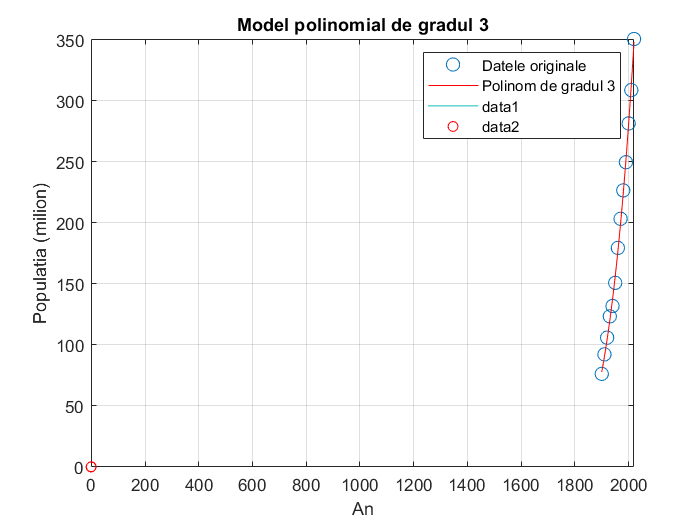

x = [-1.024940; -0.949898; -0.866114; -0.773392; -0.671372; -0.559524; -0.437067; -0.302909; -0.159493; -0.007464];
y = [-0.389269; -0.322894; -0.265256; -0.216557; -0.177152; -0.147582; -0.128618; -0.121353; -0.127348; -0.148895];

A = [y.^2, x.*y, x, y, ones(size(x))];
bv = x.^2;
coef = A \ bv;
a = coef(1); b=coef(2); c = coef(3); d=coef(4); e = coef(5);
u = linspace(min(x), max(x), 20);
v = linspace(min(y), max(y), 20);
[X,Y]=meshgrid(u,v);
Z=a*Y.^2 + b*X.*Y + c*X + d*Y + e - X.^2;
contour(X,Y,Z,[0,0]); hold on
plot(x,y,'ro'); hold on

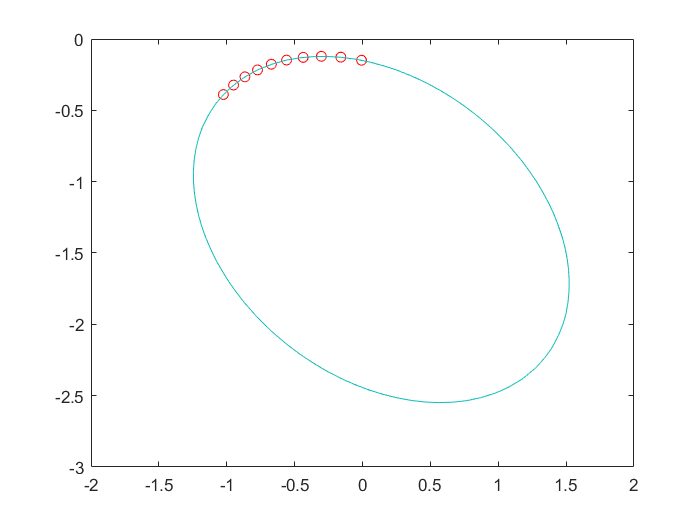

figure()
plot(x,y,'ro'); hold on
u = linspace(-2,2,40);
v=linspace(-3,0,40);
[X,Y] = meshgrid(u,v);
Z=a*Y.^2 + b*X.*Y + c*X + d*Y + e - X.^2;
contour(X,Y,Z,[0,0]);

#### Eroarea

err=sum((a*y.^2 + b*x.*y + c*x + d*y + e - x.^2).^2).^(1/2)

err = 0.0011

errb=norm(a*y.^2 + b*x.*y + c*x + d*y + e - x.^2)

errb = 0.0011

### Modelul parabolic

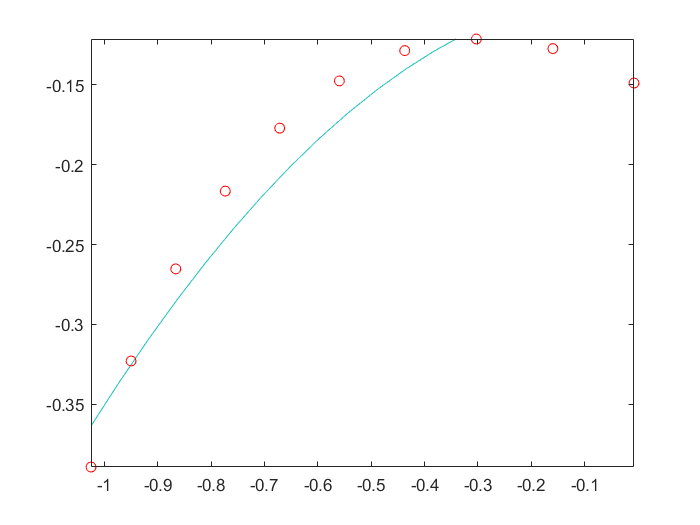

figure()
A2 = [y, ones(size(x))];
coef2=A2\bv;
a=coef2(1); e = coef2(2);
u = linspace(min(x), max(x), 20);
v = linspace(min(y), max(y), 20);
[X,Y]=meshgrid(u,v);
Z= a*Y + e - X.^2;
contour(X,Y,Z,[0,0]); hold on
plot(x,y,'ro'); hold on

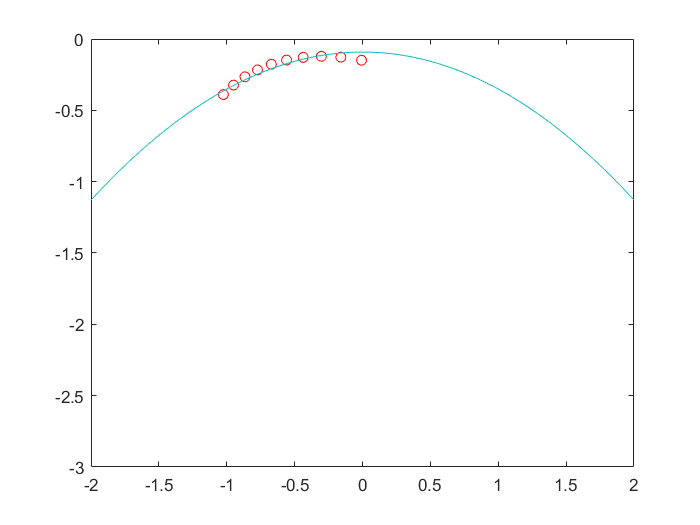

figure()
plot(x,y,'ro'); hold on
u = linspace(-2,2,40);
v=linspace(-3,0,40);
[X,Y] = meshgrid(u,v);
Z= a*Y + e - X.^2;
contour(X,Y,Z,[0,0]);

#### Eroarea

err=sum((a*y + e - x.^2).^2).^(1/2)

err = 0.3433

errb=norm(a*y + e - x.^2)

errb = 0.3433

## Probleam 3

A = [1 0 0;
     1 1 0;
     0 1 1;
     1 1 1;
     0 0 1];

b = [35; 67; 53; 89; 20];

x = A \ b;

disp(['x1 (AB) = ', num2str(x(1))])

x1 (AB) = 35.125


disp(['x2 (BC) = ', num2str(x(2))])

x2 (BC) = 32.5


disp(['x3 (CD) = ', num2str(x(3))])

x3 (CD) = 20.625


## Problema 4

x = (1900:10:2020)';
y = [75.995 91.972 105.710 123.200 131.670 150.700 179.320 203.210 226.510 249.630 281.420 308.790 350.686];

#### Modelul polinomial

p = polyfit(x, y, 3);


t_1975 = 1975;
t_2015 = 2015;
y_1975_poly = polyval(p, t_1975);
y_2015_poly = polyval(p, t_2015);

disp(['Estimarea populatiei in 1975 (polinomial): ', num2str(y_1975_poly)]);

Estimarea populatiei in 1975 (polinomial): 211.4851


disp(['Estimarea populatiei in 2015 (polinomial): ', num2str(y_2015_poly)]);

Estimarea populatiei in 2015 (polinomial): 330.29


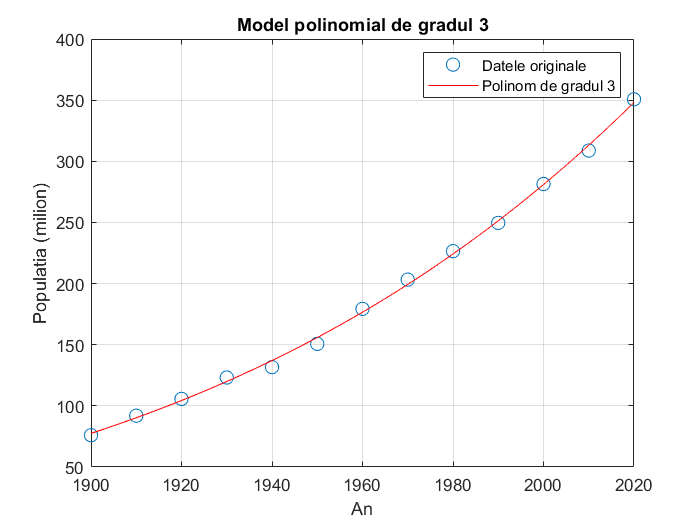

figure;
plot(x, y, 'o', 'MarkerSize', 8);
hold on;
t_fine = linspace(1900, 2020, 100);
y_poly = polyval(p, t_fine);
plot(t_fine, y_poly, '-r');
xlabel('An');
ylabel('Populatia (milion)');
title('Model polinomial de gradul 3');
legend('Datele originale', 'Polinom de gradul 3');
grid on;

#### Modelul exponential

y_log = log(y); 

p_exp = polyfit(x, y_log, 1); 
lambda = p_exp(1);
ln_K = p_exp(2);
K = exp(ln_K); 

y_1975_exp = K * exp(lambda * t_1975);
y_2015_exp = K * exp(lambda * t_2015);

disp(['Estimarea populatiei in 1975 (exponential): ', num2str(y_1975_exp)]);

Estimarea populatiei in 1975 (exponential): 207.0367


disp(['Estimarea populatiei in 2015 (exponential): ', num2str(y_2015_exp)]);

Estimarea populatiei in 2015 (exponential): 340.5983


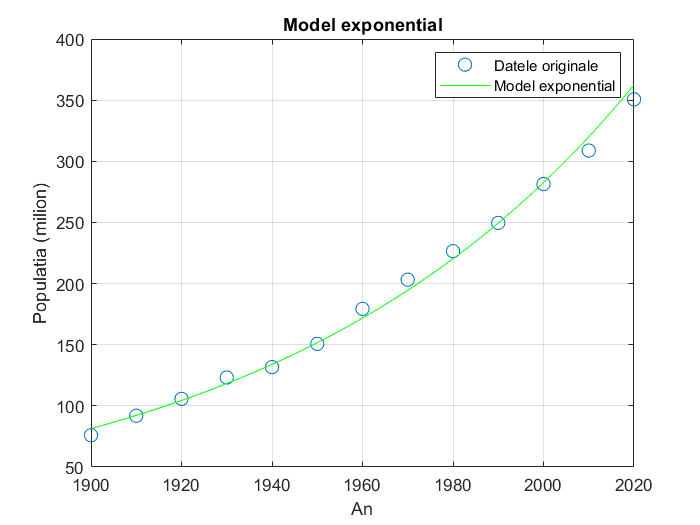


figure;
plot(x, y, 'o', 'MarkerSize', 8); 
hold on;
y_exp = K * exp(lambda * t_fine);
plot(t_fine, y_exp, '-g'); 
xlabel('An');
ylabel('Populatia (milion)');
title('Model exponential');
legend('Datele originale', 'Model exponential');
grid on;

function c = mcmmpdiscr(x, y, n)
    x = x(:); % Asigură-te că x este un vector coloană
    y = y(:); % Asigură-te că y este un vector coloană
    B = ones(length(x), n+1); % Creăm matricea B
    for j = n: -1: 1
        B(:, n-j+1) = x.^(j-1);
    end
    [Q, R] = qr(B);
    c = R \ (Q' * y);
end


function c = weightdelsq(x,y,n,w)
x = x(:); y = y(:);
B = ones(length(x),n+1);
for j = n: -1: 1
    B(:,n-j+1) = x.^j;
end
W=diag(w);
B = B*W;
[Q,R] = qr(B);
c = R\(Q'*y);
end